# Show Thermoeconomic State Demo

Use ThermoeconomicState function to obtain the exergy balances and Table FP

#### Read the Data Model

file="D:\Documents\Termoeconomia\TaesLab\Examples\rorc\rorc_model.json";
data=ReadDataModel(file);

#### Select the State to display

States=convertCharsToStrings(data.States);
State=convertStringsToChars(States(2));

#### Get the exergy values 

res=ThermoeconomicState(data,'State',State);
printResults(res);

Flows Exergy Table

Key   From    To             B(kW)
———————————————————————————————————
B1    BLR_P1  TRB_F1        82.730
B2    TRB_F1  IHE_F1        22.210
B3    IHE_F1  CND_F1        19.940
B4    CND_F1  PMP_P1         6.141
B5    PMP_P1  IHE_P1         8.203
B6    IHE_P1  BLR_P1         9.984
QBLR  ENV_R1  BLR_F1        96.960
WP    TRB_P1  PMP_F1         2.404
WN    TRB_P1  ENV_O1        46.030
QCND  CND_P1  ENV_W1        13.799


Productive Groups Exergy Table

Key            E(kW)      ET(kW)
—————————————————————————————————
BLR_F1        96.960      96.960
BLR_P1        72.746      82.730
TRB_F1        60.520      82.730
TRB_P1        48.434      48.434
IHE_F1         2.270      22.210
IHE_P1         1.781       9.984
PMP_F1         2.404       2.404
PMP_P1         2.062       8.203
CND_F1        13.799      19.940
CND_P1        13.799      13.799
ENV_R1        96.960      96.960
ENV_O1        46.030      46.030
ENV_W1        13.799      13.799


Processes Exergy Table

Key

#### Show the Diagram FP

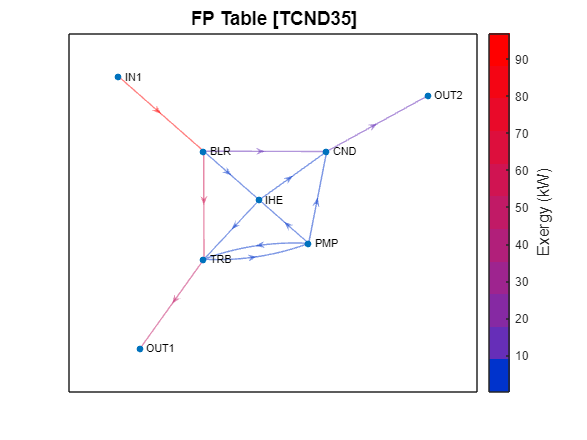

showGraph(res,'tfp')